# Homework_4_Problem_5_4

clear; close; clc;

## Declare variables

% plotting parameters
domain = [-5,5];
range = [-5,5];
n_pointsPlot = 10000;


## Plot cost function

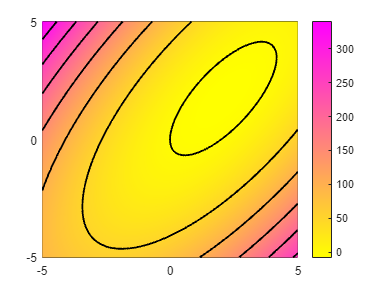

% plot the cost function
% colours
fcontour(@(x_1,x_2) 4*x_1^2 + 3*x_2^2 -5*x_1*x_2 -8*x_1, "Fill","on", "XRange", domain, "YRange",range, "MeshDensity",71, "LineColor","none", "LevelStep",1); colormap(flipud(spring));
colorbar;
hold on;
% lines
fcontour(@(x_1,x_2) 4*x_1^2 + 3*x_2^2 -5*x_1*x_2 -8*x_1, "Fill","off", "XRange", domain, "YRange",range, "MeshDensity",71, "LineColor",[0,0,0], "LineWidth",1.5, "HandleVisibility","callback"); colormap(flipud(spring));

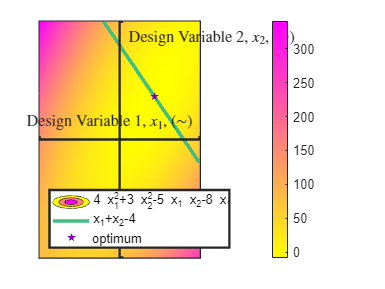


% plot the constraint function
fimplicit(@(x_1,x_2) x_1+x_2-4, domain, "-", "Color",[.25,.75,.5],"LineWidth",3);

% plot the omptimum
plot(41/19,35/19,"Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[.5,0,.75],"MarkerFaceColor",[.5,0,.75],"LineStyle","none", "DisplayName","optimum")

legend("Location","southwest")
set(gca,"FontSize",12)
set(gca,'BoxStyle','back','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)
xlabel("Design Variable 1, $x_1$, $\left(\sim\right)$", "Interpreter","latex");
ylabel("Design Variable 2, $x_2$, $\left(\sim\right)$", "Interpreter","latex")


% [v,Lambda] = eigs([8,-5;-5,6])
% fimplicit(@(x_1,x_2) x_1*v(1,1) + x_2*v(2,1), "-r" , "DisplayName", sprintf("Eig. vect. \\lambda = %g", Lambda(1,1)))
% fimplicit(@(x_1,x_2) x_1*v(1,2) + x_2*v(2,2), "-b", "DisplayName", sprintf("Eig. vect. \\lambda = %g", Lambda(2,2)))

% A = [8, -5, 1;...
%      6, -5, 1;...
%      1,  1, 0];
% inv(A)
% c = [0;0;4];
% 
% inv(A)*c

%a = fminsearch( @(x_1,x_2) 4*x_1.^2 + 3*x_2.^2 -5*x_1.*x_2, [5,5])

% figure
% x_1 = linspace(domain(1), domain(2), floor(sqrt(n_pointsPlot)));
% x_2 = linspace(range(1), range(2), floor(sqrt(n_pointsPlot)));
% 
% [x_1_grid, x_2_grid] = meshgrid(x_1,x_2);
% 
% f = 4*x_1_grid.^2 + 3*x_2_grid.^2 -5*x_2_grid.*x_1_grid;
% 
% contourf(x_1_grid, x_2_grid, f, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap(flipud(spring)); colorbar;
% hold on; fimplicit(@(x_1,x_2) x_1+x_2-4, domain, "-", "Color",[.25,.75,.5],"LineWidth",3);